# Statistics and Graphs for VR Conference Paper

June 10, 2023

Sam Michalka

There are two other notebooks that dive deeper into statistics exploration and preprocessing for these datasets. This notebook just pulls in the preprocessed data and does the stats and graphs for the final paper. PhysiologicalAnalysis.mlx and VRfreqStatAnalysisBySam.mlx

The data are loaded from .mat files, which are based on variables from the other scripts (so see those scripts for details about getting from a .csv format to this format).

The behavioral, GSR, HR, and Pupil Dilation data come directly from Ted (so Ted will need to write how those were analyzed). The EEG data were extracted by Sam using the spectoto function, followed by the conversion to absolute power, as described here: [https://sccn.ucsd.edu/wiki/Makoto%27s_useful_EEGLAB_code#How.](https://sccn.ucsd.edu/wiki/Makoto%27s_useful_EEGLAB_code#How.) Because these data are very skewed, I then took the log of them and converted them back to log power spectral density, which made them much more normal (not perfectly normal, but visually normal). This variable is called logpower or mean_log powerspecdensity.  To make things consistent, the variables from the other script were renamed: long_EEG_data = long_data; long_EEGclust_data = long_EEGclust_data;

load("AllDataForVRPaper.mat");

Set this to true if you want individual plots to on;

individualOn = true; 
errorBarType = '95sem'; 

You can set the marker and font size for plots in the helper function at the bottom.

## Reasoning for Statistics

We will run two statistical analyses in this notebook. 

First, we are intersted in seeing how closely each of these metrics tracks the number of items to be remembered in the sequence (one form of cognitive load). For this, we will treat our conditions (3 to 6) as linear, numeric data and use a linear mixed model to run regression. 

REML was used. (based on some references that this gives better estimates... but you can't use it when comparing models).

For each physiological measurement, we built a linear mixed effects model using the fitlme() function in MATLAB, following the formula of "Physiological Measurement ~ 1 + Load + (1 + Load | ID)", where Load is the number of tiles in the sequence and ID is the participant ID. We chose to include Load as a fixed and random effect, allowing the slopes of the regression model to vary across individuals, as we expect to observe different rate of change in physiological responses across participants. In the case of the pupil dialation, we included an additional fixed effect of left or right eye. 

Second, we ran a paired t-test (or repeated-measures ANOVA) for each measurement to more closely relate to cognitive load in VR literature, which often compares a low versus high load [NEED REFS]. It is important to note that in many of these papers, the low load is 1 or 2 items and the high load is 3 or 4 items. Based on the estimates that working memory capacity is approximately four items, we chose to divide our data into a lower load (3 tiles in the sequence) and a high load (5 or 6 tiles in the sequence). 

Note:  we may still end up with different results, as we are closer to or exceeding capacity (or people are using chunking). 

Effect size:

There are multiple ways to calculate effect size. Based on this paper (https://www.frontiersin.org/articles/10.3389/fpsyg.2013.00863/full), I have decided that Hedges G, which is called by meanEffectSize('cohen'). When given 'cohen', the function it computes the unbiased estimate of Cohen's d, which is also sometimes called Hedge's g.

## Behavioral Performance

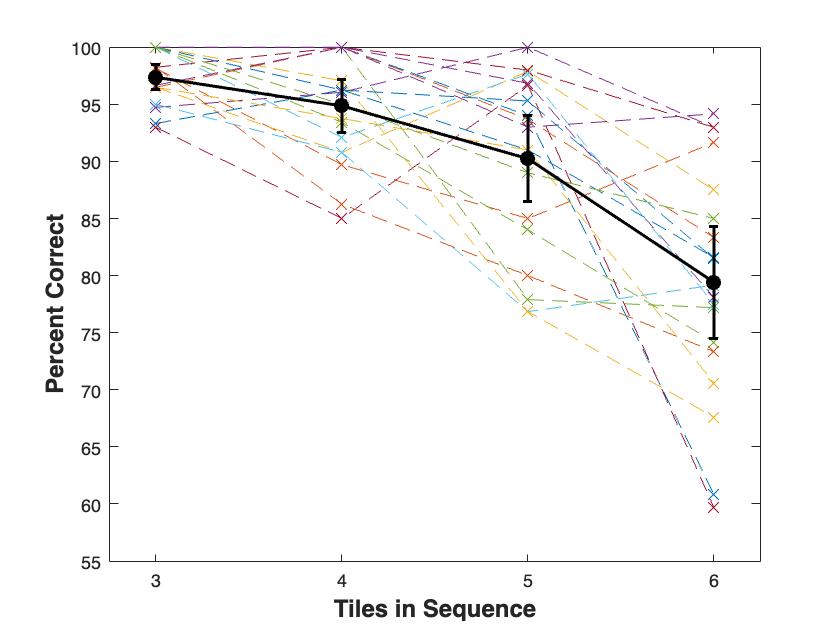

figure;

plotAgainstConditionValues(conditionValues,100.*wide_performance_data{:,string(conditions)},"Percent Correct",errorBarType,individualOn)

### Regression / LMM

% Convert values to percent correct to align with graph
if long_performance_data.Values(1) < 1
    long_performance_data.Values = 100.* long_performance_data.Values;
end
lme_performance = fitlme(long_performance_data,'Values ~ 1 + LoadVal + (1 + LoadVal|ID)', FitMethod='REML') %Load as a continuous variable

lme_performance = Linear mixed-effects model fit by REML

Model information:
    Number of observations              76
    Fixed effects coefficients           2
    Random effects coefficients         38
    Covariance parameters                4

Formula:
    Values ~ 1 + LoadVal + (1 + LoadVal | ID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    511.18    525.01    -249.59          499.18  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF    pValue        Lower      Upper  
    {'(Intercept)'}         116.79      3.3351     35.019    74    8.3096e-48     110.15     123.44
    {'LoadVal'    }        -5.8496     0.83756    -6.9842    74    1.0522e-09    -7.5185    -4.1808

Random effects covariance parameters (95% CIs):
Group: ID (19 Levels)
    Name1                  Name2                  Type      

anova(lme_performance)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        1226.4    1      74     8.3096e-48
    {'LoadVal'    }        48.778    1      74     1.0522e-09


lme_performance.Rsquared

ans = struct with fields:
    Ordinary: 0.6779
    Adjusted: 0.6736


### High-low comparison

lowValues = 100.*wide_performance_data.x3Combination;
highValues = mean(100.*[wide_performance_data.x5Combination wide_performance_data.x6Combination],2);

Compare how many subjects this holds for.

sum((highValues-lowValues)<0), sum((highValues-lowValues)>0)

ans = 18

ans = 1

mean(lowValues)

ans = 97.3679

mean(highValues)

ans = 84.8261

[~,P,CI,STATS] = ttest(highValues,lowValues)

P = 1.0153e-06

CI =   -16.1892
   -8.8943


STATS = struct with fields:
    tstat: -7.2240
       df: 18
       sd: 7.5676


Compare how many subjects this holds for.

sum((highValues-lowValues)<0), sum((highValues-lowValues)>0)

ans = 18

ans = 1

Effect size (multiple ways to do this)

effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','meandiff','Alpha',0.05)

effectSize = 1×2 table
                      Effect     ConfidenceIntervals
                      _______    ___________________

    MeanDifference    -12.542    -16.189    -8.8943 


effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','cohen','Alpha',0.05)

effectSize = 1×2 table
               Effect     ConfidenceIntervals
               _______    ___________________

    CohensD    -2.2587    -3.4681    -1.3928 


%effectSize = mean(highValues-lowValues)./std(highValues-lowValues)


## GSR

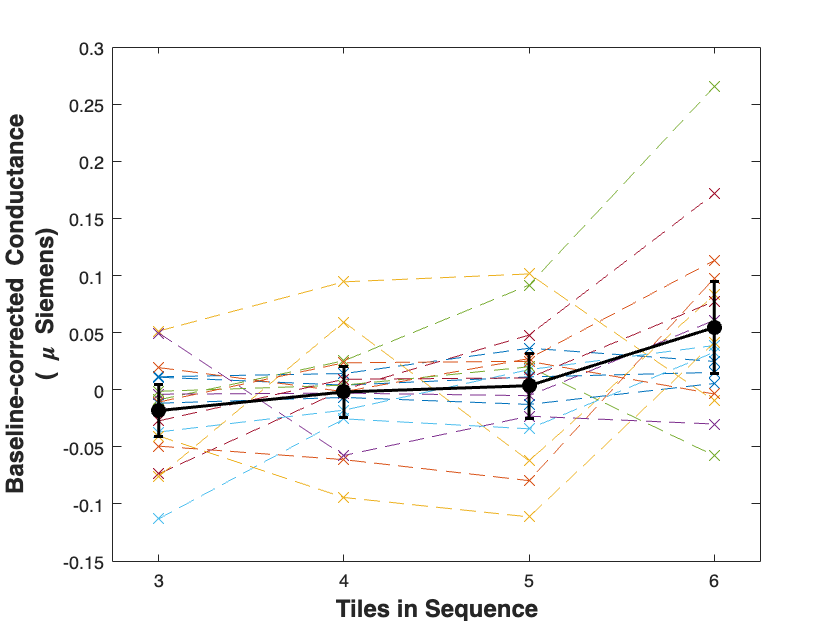

figure;
plotAgainstConditionValues(conditionValues,wide_GSR_data{:,string(conditions)},{"Baseline-corrected Conductance","( \mu Siemens)"},errorBarType,individualOn)

### Regression / LMM

lme_GSR = fitlme(long_GSR_data,'Values ~ 1 + LoadVal + (1 + LoadVal|ID)', FitMethod='REML') %Load as a continuous variable

lme_GSR = Linear mixed-effects model fit by REML

Model information:
    Number of observations              68
    Fixed effects coefficients           2
    Random effects coefficients         34
    Covariance parameters                4

Formula:
    Values ~ 1 + LoadVal + (1 + LoadVal | ID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -178.61    -165.47    95.303           -190.61 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat    DF    pValue       Lower        Upper    
    {'(Intercept)'}        -0.091279     0.031694    -2.88    66    0.0053576     -0.15456    -0.027999
    {'LoadVal'    }         0.022385    0.0074219    3.016    66    0.0036339    0.0075665     0.037203

Random effects covariance parameters (95% CIs):
Group: ID (17 Levels)
    Name1                  Name2                  Ty

anova(lme_GSR)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue   
    {'(Intercept)'}        8.2942    1      66     0.0053576
    {'LoadVal'    }        9.0965    1      66     0.0036339


lme_GSR.Rsquared

ans = struct with fields:
    Ordinary: 0.5347
    Adjusted: 0.5276


### High-low comparison

lowValues = wide_GSR_data.x3Combination;
highValues = mean([wide_GSR_data.x5Combination wide_GSR_data.x6Combination],2);
mean(lowValues)

ans = -0.0183

mean(highValues)

ans = 0.0290

[~,P,CI,STATS] = ttest(highValues,lowValues)

P = 0.0112

CI =     0.0123
    0.0823


STATS = struct with fields:
    tstat: 2.8641
       df: 16
       sd: 0.0681


mean(lowValues)

ans = -0.0183

mean(highValues)

ans = 0.0290

Compare how many subjects this holds for.

sum((highValues-lowValues)<0), sum((highValues-lowValues)>0)

ans = 3

ans = 14

Effect size (multiple ways to do this)

effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','meandiff','Alpha',0.05)

effectSize = 1×2 table
                       Effect     ConfidenceIntervals 
                      ________    ____________________

    MeanDifference    0.047302    0.012291    0.082312


effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','cohen','Alpha',0.05)

effectSize = 1×2 table
               Effect     ConfidenceIntervals
               _______    ___________________

    CohensD    0.93385    0.21736     1.8222 


%effectSize = mean(highValues-lowValues)./std(highValues-lowValues)

## HR

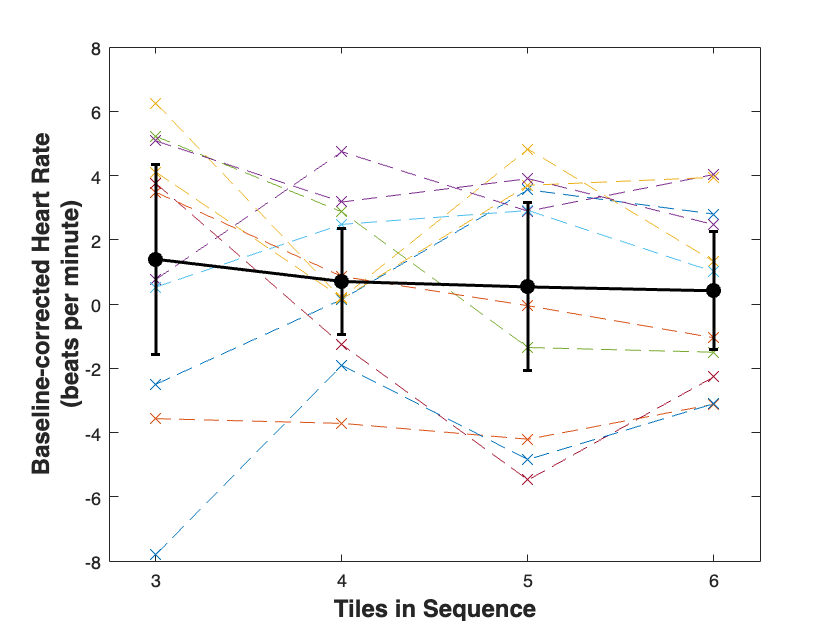

figure;
plotAgainstConditionValues(conditionValues,wide_HR_data{:,string(conditions)},{"Baseline-corrected Heart Rate","(beats per minute)"},errorBarType,individualOn)

### Regression / LMM

lme_HR = fitlme(long_HR_data,'Values ~ 1 + LoadVal + (1 + LoadVal|ID)', FitMethod='REML') %Load as a continuous variable

lme_HR = Linear mixed-effects model fit by REML

Model information:
    Number of observations              44
    Fixed effects coefficients           2
    Random effects coefficients         22
    Covariance parameters                4

Formula:
    Values ~ 1 + LoadVal + (1 + LoadVal | ID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    224.82    235.25    -106.41          212.82  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat       DF    pValue     Lower      Upper  
    {'(Intercept)'}          2.1644     2.1002      1.0305    42    0.30865    -2.0741     6.4028
    {'LoadVal'    }        -0.31141    0.40842    -0.76248    42    0.45004    -1.1356    0.51282

Random effects covariance parameters (95% CIs):
Group: ID (11 Levels)
    Name1                  Name2                  Type            Estimate 

anova(lme_HR)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2    pValue 
    {'(Intercept)'}          1.062    1      42     0.30865
    {'LoadVal'    }        0.58137    1      42     0.45004


lme_HR.Rsquared

ans = struct with fields:
    Ordinary: 0.7209
    Adjusted: 0.7143


### High-low comparison

lowValues = wide_HR_data.x3Combination;
highValues = mean([wide_HR_data.x5Combination wide_HR_data.x6Combination],2);
mean(lowValues)

ans = 1.3964

mean(highValues)

ans = 0.4752

[~,P,CI,STATS] = ttest(highValues,lowValues)

P = 0.4832

CI =    -3.7400
    1.8975


STATS = struct with fields:
    tstat: -0.7282
       df: 10
       sd: 4.1957


Compare how many subjects this holds for.

sum((highValues-lowValues)<0), sum((highValues-lowValues)>0)

ans = 7

ans = 4

Effect size (multiple ways to do this)

effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','meandiff','Alpha',0.05)

effectSize = 1×2 table
                       Effect     ConfidenceIntervals
                      ________    ___________________

    MeanDifference    -0.92125      -3.74    1.8975  


effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','cohen','Alpha',0.05)

effectSize = 1×2 table
                Effect     ConfidenceIntervals 
               ________    ____________________

    CohensD    -0.21993    -0.99119     0.48234


%effectSize = mean(highValues-lowValues)./std(highValues-lowValues)

## Eye / Pupil Dilation

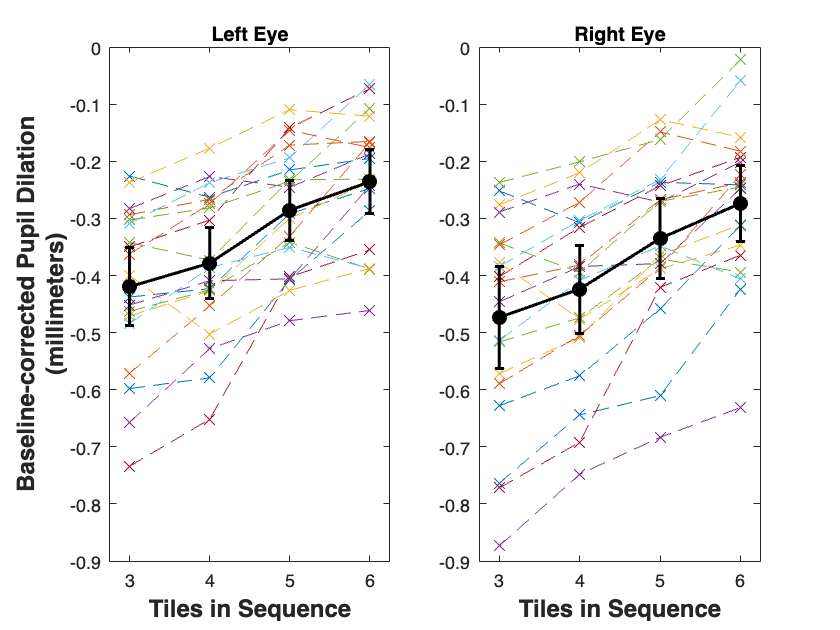

figure;
subplot(1,2,1)
plotAgainstConditionValues(conditionValues,wide_eye_data{:,2:2:end},{"Baseline-corrected Pupil Dilation","(millimeters)"},errorBarType,individualOn);
ylim([-0.9 0]); % make the ylims the same for the two graphs
title("Left Eye")
subplot(1,2,2)
plotAgainstConditionValues(conditionValues,wide_eye_data{:,3:2:end},"",errorBarType,individualOn);
ylim([-0.9 0]); % make the ylims the same for the two graphs
title("Right Eye")

### Regression / LMM

lme_eye = fitlme(long_eye_data,'Values ~ 1 + LoadVal + Eye + (1 + LoadVal|ID)', FitMethod='REML') %Load as a continuous variable

lme_eye = Linear mixed-effects model fit by REML

Model information:
    Number of observations             152
    Fixed effects coefficients           3
    Random effects coefficients         38
    Covariance parameters                4

Formula:
    Values ~ 1 + Eye + LoadVal + (1 + LoadVal | ID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -319.74    -298.71    166.87           -333.74 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF     pValue        Lower        Upper    
    {'(Intercept)'}         -0.62934     0.056298    -11.179    149    1.8882e-21     -0.74059     -0.51809
    {'Eye_Right'  }        -0.046661    0.0090314    -5.1665    149    7.5362e-07    -0.064507    -0.028815
    {'LoadVal'    }         0.066591    0.0083137     8.0098    149    3.0419e-13     0.050163     0.083019

Rando

anova(lme_eye)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        124.96    1      149    1.8882e-21
    {'Eye'        }        26.693    1      149    7.5362e-07
    {'LoadVal'    }        64.157    1      149    3.0419e-13


lme_eye.Rsquared

ans = struct with fields:
    Ordinary: 0.9002
    Adjusted: 0.8989


### High-low comparison

% Left Eye
lowValues = wide_eye_data.left_x3Combination;
highValues = mean([wide_eye_data.left_x5Combination wide_eye_data.left_x6Combination],2);
mean(lowValues)

ans = -0.4195

mean(highValues)

ans = -0.2605

[~,P,CI,STATS] = ttest(highValues,lowValues)

P = 5.9778e-07

CI =     0.1145
    0.2035


STATS = struct with fields:
    tstat: 7.5081
       df: 18
       sd: 0.0923


Compare how many subjects this holds for.

sum((highValues-lowValues)<0), sum((highValues-lowValues)>0)

ans = 1

ans = 18

Effect size (multiple ways to do this)

effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','meandiff','Alpha',0.05)

effectSize = 1×2 table
                      Effect     ConfidenceIntervals
                      _______    ___________________

    MeanDifference    0.15903    0.11453    0.20352 


effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','cohen','Alpha',0.05)

effectSize = 1×2 table
               Effect    ConfidenceIntervals
               ______    ___________________

    CohensD    1.2053    0.75186     1.8413 


%effectSize = mean(highValues-lowValues)./std(lowValues-highValues)

% Right eye
lowValues = wide_eye_data.right_x3Combination;
highValues = mean([wide_eye_data.right_x5Combination wide_eye_data.right_x6Combination],2);
mean(lowValues)

ans = -0.4732

mean(highValues)

ans = -0.3043

[~,P,CI,STATS] = ttest(highValues,lowValues)

P = 2.9663e-07

CI =     0.1239
    0.2138


STATS = struct with fields:
    tstat: 7.8932
       df: 18
       sd: 0.0933


Compare how many subjects this holds for.

sum((highValues-lowValues)<0), sum((highValues-lowValues)>0)

ans = 0

ans = 19

Effect size (multiple ways to do this)

effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','meandiff','Alpha',0.05)

effectSize = 1×2 table
                      Effect     ConfidenceIntervals
                      _______    ___________________

    MeanDifference    0.16886    0.12392    0.21381 


effectSize  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','cohen','Alpha',0.05)

effectSize = 1×2 table
               Effect     ConfidenceIntervals
               _______    ___________________

    CohensD    0.99003    0.62618     1.5032 


%effectSize = mean(highValues-lowValues)./std(highValues-lowValues)

#### Make a table of the stats for the non-EEG sensors LMMs.

tableNonEEGLMM  = putLMEresultsTable(lme_performance,"Behavioral");
tableNonEEGLMM  = [tableNonEEGLMM; putLMEresultsTable(lme_GSR,"GSR")];
tableNonEEGLMM  = [tableNonEEGLMM; putLMEresultsTable(lme_eye,"PD")];
tableNonEEGLMM  = [tableNonEEGLMM; putLMEresultsTable(lme_HR,"HR")];

Make table for means and stds of non-EEG sensors.


tableNonEEGmeans = table("Behavioral", "mean", mean(100*wide_performance_data.x3Combination), mean(100*wide_performance_data.x4Combination), mean(100*wide_performance_data.x5Combination), mean(100*wide_performance_data.x6Combination),...
    'VariableNames',["Measurement","Stat","3","4","5","6"]);
tableNonEEGmeans(2,:) = table("Behavioral", "std", std(100*wide_performance_data.x3Combination), std(100*wide_performance_data.x4Combination), std(100*wide_performance_data.x5Combination), std(100*wide_performance_data.x6Combination));
tableNonEEGmeans(3,:) = table("GSR", "mean", mean(wide_GSR_data.x3Combination), mean(wide_GSR_data.x4Combination), mean(wide_GSR_data.x5Combination), mean(wide_GSR_data.x6Combination));
tableNonEEGmeans(4,:) = table("GSR", "std", std(wide_GSR_data.x3Combination), std(wide_GSR_data.x4Combination), std(wide_GSR_data.x5Combination), std(wide_GSR_data.x6Combination));
tableNonEEGmeans(5,:) = table("Left PD", "mean", mean(wide_eye_data.left_x3Combination), mean(wide_eye_data.left_x4Combination), mean(wide_eye_data.left_x5Combination), mean(wide_eye_data.left_x6Combination));
tableNonEEGmeans(6,:) = table("Left PD", "std", std(wide_eye_data.left_x3Combination), std(wide_eye_data.left_x4Combination), std(wide_eye_data.left_x5Combination), std(wide_eye_data.left_x6Combination));
tableNonEEGmeans(7,:) = table("Right PD", "mean", mean(wide_eye_data.right_x3Combination), mean(wide_eye_data.right_x4Combination), mean(wide_eye_data.right_x5Combination), mean(wide_eye_data.right_x6Combination));
tableNonEEGmeans(8,:) = table("Right PD", "std", std(wide_eye_data.right_x3Combination), std(wide_eye_data.right_x4Combination), std(wide_eye_data.right_x5Combination), std(wide_eye_data.right_x6Combination));
tableNonEEGmeans(9,:) = table("HR", "mean", mean(wide_HR_data.x3Combination), mean(wide_HR_data.x4Combination), mean(wide_HR_data.x5Combination), mean(wide_HR_data.x6Combination));
tableNonEEGmeans(10,:) = table("HR", "std", std(wide_HR_data.x3Combination), std(wide_HR_data.x4Combination), std(wide_HR_data.x5Combination), std(wide_HR_data.x6Combination))

tableNonEEGmeans = 10×6 table
    Measurement      Stat         3            4             5           6    
    ____________    ______    _________    __________    _________    ________

    "Behavioral"    "mean"       97.368        94.864       90.243       79.41
    "Behavioral"    "std"        2.3072        4.7761       7.8115      10.234
    "GSR"           "mean"    -0.018279    -0.0019579    0.0035416    0.054504
    "GSR"           "std"      0.043732      0.043947     0.055298    0.078186
    "Left PD"       "mean"     -0.41953      -0.37818     -0.28538    -0.23563
    "Left PD"       "std"       0.14272       0.12942      0.10922     0.11552
    "Right PD"      "mean"     -0.47316      -0.42359     -0.33503    -0.27358
    "Right PD"      "std"       0.18596        0.1599 

## EEG

Select which frequency bands you want to include for the EEG analysis. If you include all, this is redundant information (e.g., high and low alpha and alpha).

The values from spectopo are

"Log Power Spectral Density 10*log_{10}(\muV^{2}/Hz)' 

We then calculate the absolute power via

 `mean``(``10``.^``(``spectra``(``deltaIdx``)``/``10``)``)``;`

`So  ``mean``(``10``.^``(`10*log_{10}(\muV^{2}/Hz)`/``10``)``)``;`

`mean(10.^(`log_{10}(\muV^{2}/Hz)`);`

`mean(`\muV^{2}/Hz))

But these results give a very skewed distribution, so I converted back to 10*log10(abspower) for the stats.  I did this much later, so we just need to fix things here.

long_EEG_data = long_data;
long_EEGclust_data = chclust_long_data_lppsd;

Select which bands to include.

%bands = freqBands.Names; 
% bands = ["delta",...
%     "theta",...
%     "alpha",...
%     "beta",...
%     "lowerAlpha",...
%     "upperAlpha",...
%     "lowerBeta",...
%     "upperBeta"];
bands = ["delta",...
    "theta",...
    "lowerAlpha",...
    "upperAlpha",...
    "lowerBeta",...
    "upperBeta"];


### Regression / LMM

Loop through each band and channel cluster. Then correct for multiple comparisons, since we're doing several tests on these data.


uncorrected_p_value_band_chclust_reg = zeros(length(bands),length(channel_cluster_names));
i = 1;
for b = 1:length(bands)
    for ch = 1:length(channel_cluster_names)
        
        temp_data = long_EEGclust_data(long_EEGclust_data.band==bands{b} & long_EEGclust_data.channelCluster==channel_cluster_names(ch),:);
        %lme_tempEEG = fitlme(temp_data,'mean_logpower ~ 1 + combination + (1 + combination|id)'); % From old version using just log
        lme_tempEEG = fitlme(temp_data,'mean_logpowerspecdensity ~ 1 + combination + (1 + combination|id)','FitMethod','REML');
        uncorrected_p_value_band_chclust_reg(b,ch) = lme_tempEEG.Coefficients.pValue(2); % Extract pvalues for load
        
        if i == 1
            resultsTable_EEG  = putLMEresultsTable(lme_tempEEG,"EEG");
        else
            resultsTable_EEG  = [resultsTable_EEG; putLMEresultsTable(lme_tempEEG,"EEG")];
        end

%         if lme_tempEEG.Coefficients.pValue(2) < 0.05
%             disp("Significant uncorrected")
%             disp("----------Analysis for -----------------------------------")
%             bands(b)
%             channel_cluster_names(ch)
%             lme_tempEEG
%             anova(lme_tempEEG)
%             lme_tempEEG.Rsquared
%         end
%         disp(" ")
        i = i + 1;

    end
end



If you want to do manual corrections for multiple comparison, you'll need: [https://www.mathworks.com/matlabcentral/fileexchange/28303-bonferroni-holm-correction-for-multiple-comparisons](https://www.mathworks.com/matlabcentral/fileexchange/28303-bonferroni-holm-correction-for-multiple-comparisons) or some similar function. See bonf_holm() below.

addpath('/Users/smichalka/Documents/Matlab/bonf_holm/')

First, plot the corrected and uncorrected p-values for the continuous linear mixed model (LMM).

resultsTable_EEG.correctedPvalueBH = bonf_holm(resultsTable_EEG.pValue); % need to add path after downloading toolbox (or find another)
resultsTable_EEG.correctedPvalueFDR = fdr(resultsTable_EEG.pValue); % Need eeglab open for this.

%figure;
%imagesc(uncorrected_p_value_band_chclust_reg); clim([0 0.05]); colorbar; colormap('pink');
%xticks(1:length(channel_cluster_names)); xticklabels(channel_cluster_names);
%yticks(1:length(bands)); yticklabels(bands);
%title('Uncorrected p-values for continuous load LMM');
uncorrected_p_value_band_chclust_reg

uncorrected_p_value_band_chclust_reg =     0.0000    0.0007    0.0023
    0.3399    0.3874    0.7980
    0.0731    0.0223    0.2889
    0.0242    0.0221    0.0429
    0.0724    0.0079    0.0002
    0.9370    0.2153    0.1218


corrected_p_value_band_chclust_reg = bonf_holm(uncorrected_p_value_band_chclust_reg)

corrected_p_value_band_chclust_reg =     0.0002    0.0111    0.0338
    1.4447    1.3594    1.5959
    0.6516    0.2868    1.4447
    0.2671    0.2868    0.4285
    0.6516    0.1107    0.0035
    1.5959    1.2920    0.8523


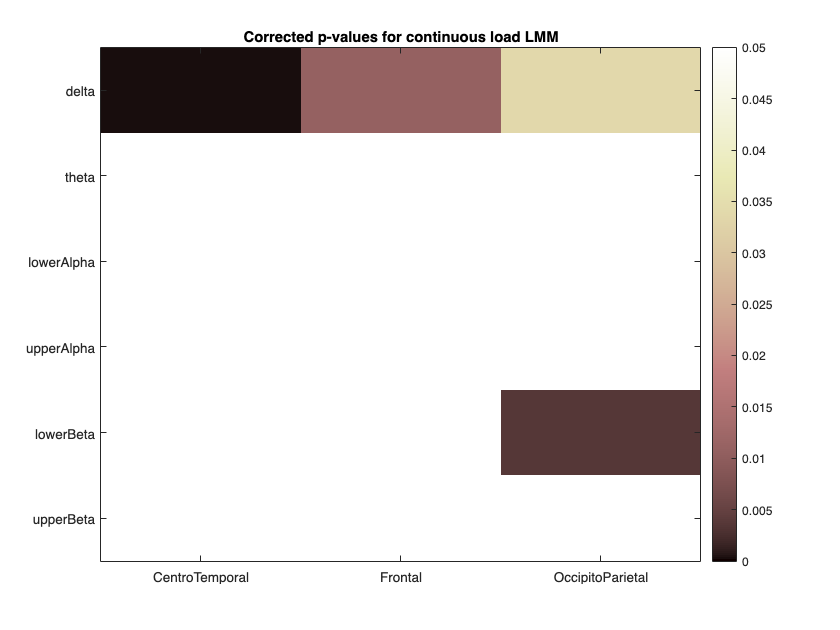

%corrected_p_value_band_chclust_reg = fdr(uncorrected_p_value_band_chclust_reg)
figure;
imagesc(corrected_p_value_band_chclust_reg); clim([0 0.05]); colorbar; colormap('pink');
xticks(1:length(channel_cluster_names)); xticklabels(channel_cluster_names);
yticks(1:length(bands)); yticklabels(bands);
title('Corrected p-values for continuous load LMM');

### Plots

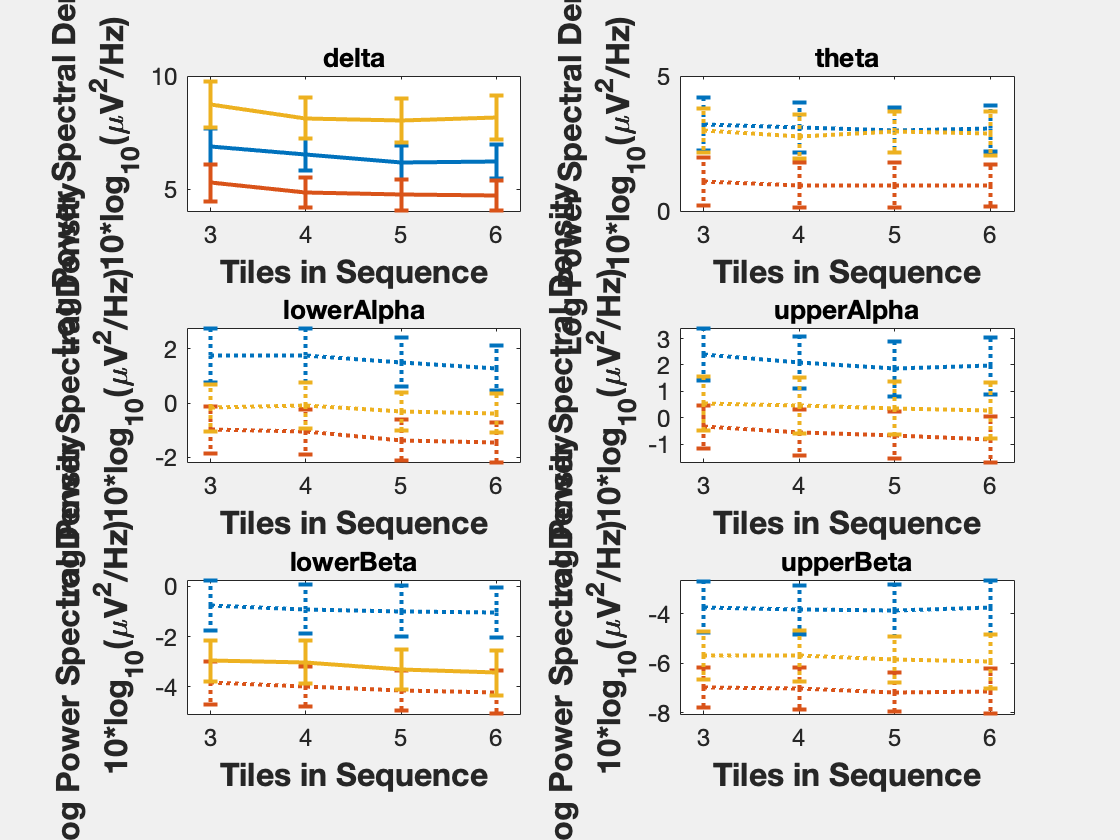


% group average
sigcorp = corrected_p_value_band_chclust_reg < 0.05;
numsig = sum(sum(sigcorp));
numSubj = length(unique(long_EEGclust_data.id));
CI95 = tinv([0.025 0.975], numSubj-1);
% We have to force this figure to pop out because the error bars won't be
% dashed otherwise.
figure; set(gcf,'Visible','on') 
for b = 1:length(bands)
    legendtext = [];
    for cl = 1:length(channel_cluster_names)
        subdata = long_EEGclust_data(long_EEGclust_data.band==bands(b) & long_EEGclust_data.channelCluster==channel_cluster_names(cl),:);
        
        subplot(length(bands)/2,2,b)

        %sumstatsub = grpstats(subdata,"combination",["mean","sem"],"DataVars","mean_logpower","VarNames",["combination","GroupCount","mean","sem"]);

        sumstatsub = grpstats(subdata,"combination",["mean","sem"],"DataVars","mean_logpowerspecdensity","VarNames",["combination","GroupCount","mean","sem"]);
        
        if sigcorp(b,cl) % if sig, make plot
            lineStyle = '-';
        else
            lineStyle = ':';
        end
    
        eb = errorbar(sumstatsub.combination,sumstatsub.mean,CI95(2).*sumstatsub.sem,'LineStyle',lineStyle,'LineWidth',2);
        if ~sigcorp(b,cl) % if sig, make plot
            
            eb.Bar.LineStyle = 'dotted';
        end

        hold on;
                      
    end
    fontsize(gca,12,'points')
    xlim([2.75 6.25]); xlabel('Tiles in Sequence','FontSize',16,"FontWeight","bold");
    ylabel({"Log Power Spectral Density", "10*log_{10}(\muV^{2}/Hz)"},'FontSize',16,"FontWeight","bold");
    title(strcat(bands{b}));
    if b ==1
        %legend(channel_cluster_names)
    end

    hold off;
end

### High-low comparison

For this comparison, we will look in each frequency band separately (since we know they will have different values). We'll do a repeated measures ANOVA to compare the low-high load conditions and the region. If there is a main effect or interaction of region, then we will do post-hoc tests to see if 

Repeated measures ANOVAs expect the data to be in a wide format instead of long, so we will reshape it here.

% For each band, reshape the data and group for low / high
wide_EEG_clust = unstack(long_EEGclust_data(ismember(long_EEGclust_data.band,categorical(bands)),["id",'band',"combinationOrdinal","channelCluster","mean_logpowerspecdensity"]),"mean_logpowerspecdensity","combinationOrdinal");

wide_EEG_clust.lowLoad = wide_EEG_clust.x3;
wide_EEG_clust.highLoad = mean([wide_EEG_clust.x5 wide_EEG_clust.x6],2);
wide_EEG_clust.x3 = []; wide_EEG_clust.x4 = []; wide_EEG_clust.x5 = []; wide_EEG_clust.x6 = [];
wide_EEG_clust = unstack(wide_EEG_clust,["lowLoad","highLoad"],"channelCluster");
wide_EEG_clust = unstack(wide_EEG_clust,wide_EEG_clust.Properties.VariableNames(3:end),"band");


The repeated measures ANOVA requies a design matrix that shows the repeated variables. This is visualized below so we can confirm that our model is correct.

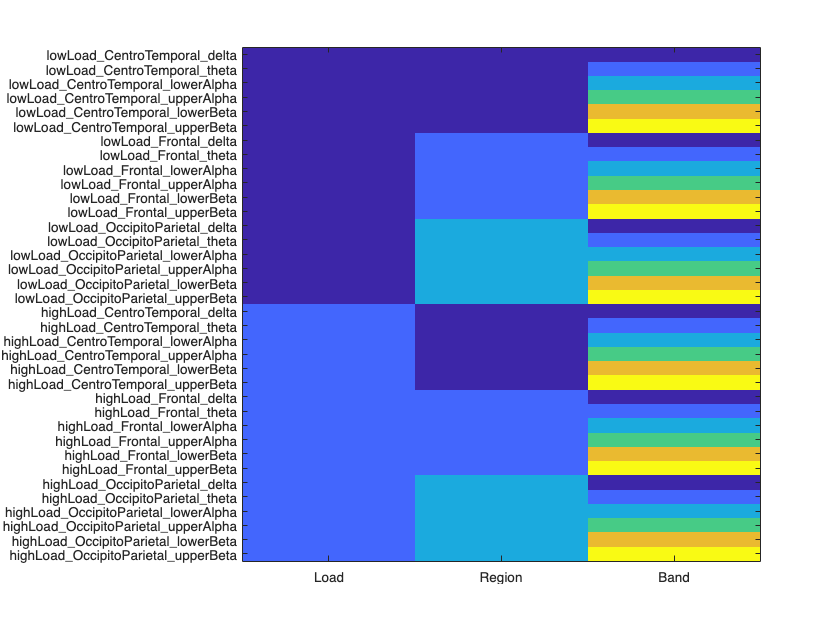

withinDesign = table([ones(1,length(bands).*length(channel_cluster_names))  2.*ones(1,length(bands).*length(channel_cluster_names))]',...
    [repmat([ones(1,length(bands)) 2.*ones(1,length(bands)) 3.*ones(1,length(bands))],1,2)]',...
    [repmat(1:length(bands),1,2.*length(channel_cluster_names))]',...
    'VariableNames',{'Load','Region','Band'});

% Plot the model
figure; imagesc(double(withinDesign{:,:})); set(gca,'defaultTextInterpreter','none','TickLabelInterpreter','none');
xticks(1:length(withinDesign.Properties.VariableNames));xticklabels(withinDesign.Properties.VariableNames); yticks(1:height(withinDesign));yticklabels(wide_EEG_clust.Properties.VariableNames(end-height(withinDesign)+1:end));

withinDesign.Load = categorical(withinDesign.Load);
withinDesign.Region = categorical(withinDesign.Region);
withinDesign.Band = categorical(withinDesign.Band);
withinDesign.RegionXBand = withinDesign.Region .* withinDesign.Band; % Create an intersection factor to use for post-hoc testing


After confirming that the model is correct, run the model that includes load, band, and region.

rm_load_region_band = fitrm(wide_EEG_clust,strcat(wide_EEG_clust.Properties.VariableNames{2},'-',wide_EEG_clust.Properties.VariableNames{end},'~ 1'),'WithinDesign',withinDesign);
AT_rm_load_region_band = ranova(rm_load_region_band,'WithinModel','Load*Region*Band')

AT_rm_load_region_band = 16×8 table
                                     SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                    ________    ___    ________    _______    __________    __________    __________    __________

    (Intercept)                       38.563      1      38.563     0.5503       0.46895       0.46895       0.46895       0.46895
    Error                             1121.2     16      70.076                                                                   
    (Intercept):Load                  15.684      1      15.684       19.6    0.00042268    0.00042268    0.00042268

We observe a 3-way interaction between Load,Region, and Band. 

rm_multcomp_load_region_band = multcompare(rm_load_region_band,'Load','By','RegionXBand'); 
half_rm_multcomp_load_region_band = rm_multcomp_load_region_band(2:2:end,:); 


% Add labels to make the table easier to understand
tempNames = wide_EEG_clust.Properties.VariableNames(2:1+height(half_rm_multcomp_load_region_band))';


tempNames = split(tempNames,"_");
half_rm_multcomp_load_region_band.Band= categorical(tempNames(:,3)); 
half_rm_multcomp_load_region_band.Region= categorical(tempNames(:,2));
half_rm_multcomp_load_region_band = sortrows(half_rm_multcomp_load_region_band, "Band", "descend");

% Add effect size measurement for each test
effectSize = zeros(height(half_rm_multcomp_load_region_band),1);
for h = 1:height(half_rm_multcomp_load_region_band)    
    tempBand = string(half_rm_multcomp_load_region_band.Band(h));
    tempRegion = string(half_rm_multcomp_load_region_band.Region(h));
    eval(strcat("highValues = wide_EEG_clust.highLoad_",tempRegion,"_",tempBand,";"))
    eval(strcat("lowValues = wide_EEG_clust.lowLoad_",tempRegion,"_",tempBand,";"))
    eS  = meanEffectSize(highValues,lowValues,'Paired',true,'Effect','cohen','Alpha',0.05);
    effectSize(h) = eS.Effect;

end
half_rm_multcomp_load_region_band.EffectSize = effectSize;

Show results table

half_rm_multcomp_load_region_band

half_rm_multcomp_load_region_band = 18×11 table
    RegionXBand    Load_1    Load_2    Difference    StdErr       pValue       Lower        Upper         Band            Region         EffectSize
    ___________    ______    ______    __________    _______    __________    ________    _________    __________    ________________    __________

        1 6          2         1       -0.068083     0.12084       0.58098    -0.32426       0.1881    upperBeta     CentroTemporal      -0.031529 
        2 6          2         1          -0.168     0.11355       0.15842     -0.4087     0.072711    upperBeta     Frontal         

Show just significant results

half_rm_multcomp_load_region_band(half_rm_multcomp_load_region_band.pValue<0.05,:)

ans = 8×11 table
    RegionXBand    Load_1    Load_2    Difference    StdErr       pValue       Lower        Upper         Band            Region         EffectSize
    ___________    ______    ______    __________    _______    __________    ________    _________    __________    ________________    __________

        1 4          2         1        -0.49154     0.17374      0.012091    -0.85984     -0.12323    upperAlpha    CentroTemporal       -0.23521 
        2 4          2         1        -0.40318     0.18139      0.040992    -0.78771     -0.01866    upperAlpha    Frontal              -0.23486 
        2 5     

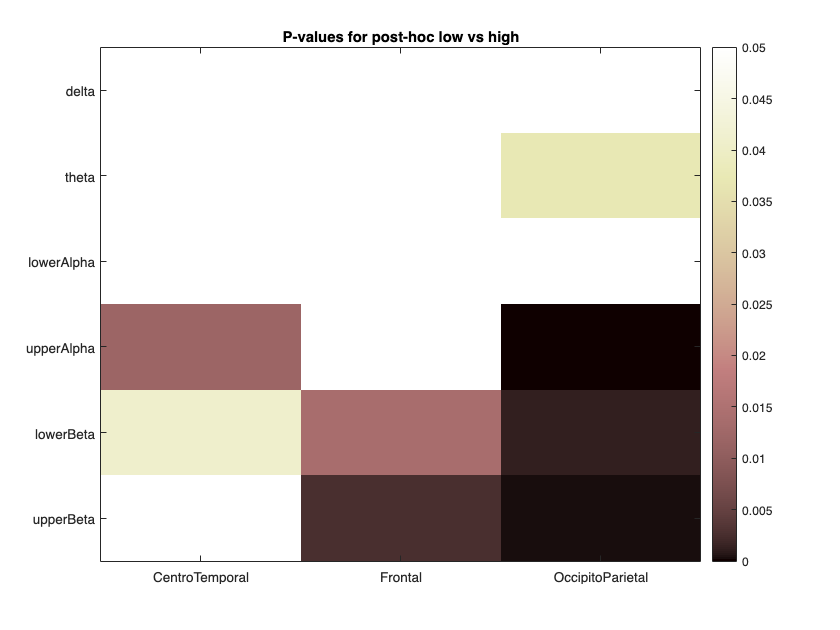

figure;
imagesc(reshape(half_rm_multcomp_load_region_band.pValue,length(bands),length(channel_cluster_names))); clim([0 0.05]); colorbar; colormap('pink');
xticks(1:length(channel_cluster_names)); xticklabels(channel_cluster_names);
yticks(1:length(bands)); yticklabels(bands);
title('P-values for post-hoc low vs high');

Make EEG mean and std table

clust = unstack(long_EEGclust_data(ismember(long_EEGclust_data.band,categorical(bands)),["id",'band',"combinationOrdinal","channelCluster","mean_logpowerspecdensity"]),"mean_logpowerspecdensity","combinationOrdinal");
cluststat = grpstats(long_EEG_data,["band","channelCluster","combination"],["mean","std"],"DataVars","logpowerspecdensity","VarNames",["Band","Channel Cluster","Tiles","GroupCount","mean","std"])
cluststatwide = unstack(cluststat,{'mean','std'},'Tiles');
%cluststat = grpstats(long_EEG_data,["band","channelCluster","combination"],["mean","std"],"DataVars","logpowerspecdensity","VarNames",["Band","Channel Cluster","Tiles","GroupCount","mean","std"])


See how many subjects this holds for

eeghighminuslow = wide_EEG_clust{:,20:end} - wide_EEG_clust{:,2:19};
sum(eeghighminuslow > 0)

ans =      1     6     7     4     4     7     2     7     5     6     4     6     2     8     6     7     1     6


sum(eeghighminuslow < 0)

ans =     16    11    10    13    13    10    15    10    12    11    13    11    15     9    11    10    16    11


wide_EEG_clust.Properties.VariableNames(20:end)

ans = 1×18 cell array
    {'highLoad_CentroTemporal_delta'}    {'highLoad_CentroTemporal_theta'}    {'highLoad_CentroTemporal_lowerAlpha'}    {'highLoad_CentroTemporal_upperAlpha'}    {'highLoad_CentroTemporal_lowerBeta'}    {'highLoad_CentroTemporal_upperBeta'}    {'highLoad_Frontal_delta'}    {'highLoad_Frontal_theta'}    {'highLoad_Frontal_lowerAlpha'}    {'highLoad_Frontal_upperAlpha'}    {'highLoad_Frontal_lowerBeta'}    {'highLoad_Frontal_upperBeta'}    {'highLoad_OccipitoParietal_delta'}    {'highLoad_OccipitoParietal_theta'}    {'highLoad_OccipitoParietal_lowerAlpha'}    {'highLoad_OccipitoParietal_upperAlpha'}    {'highLoad_OccipitoParietal_lowerBeta'}    {'highLoad_OccipitoParietal_upperBeta'}


100.*sum(eeghighminuslow < 0)./size(eeghighminuslow,1)

ans =    94.1176   64.7059   58.8235   76.4706   76.4706   58.8235   88.2353   58.8235   70.5882   64.7059   76.4706   64.7059   88.2353   52.9412   64.7059   58.8235   94.1176   64.7059



save("EverythingFromCurrentVRAnalysis.mat")

## Helper Functions

This takes in the data with subjects as rows.

function plotAgainstConditionValues(conditionValues,tempData3to6,metricLabel,errorBarType,individualOn)
    if individualOn
        for i = 1:size(tempData3to6,1)
            plot(conditionValues,tempData3to6(i,:),'x--','MarkerSize',10);
            hold on;  
        end
    end
    errorVals = calculateError(tempData3to6,errorBarType);
    errorbar(conditionValues,mean(tempData3to6),errorVals,'k','LineWidth',2);
    plot(conditionValues,mean(tempData3to6),'k.','MarkerSize',30); 
    hold off;
    fontsize(gca,12,'points')
    xlim([2.75 6.25]); xticks(3:6); xlabel('Tiles in Sequence','FontSize',16,"FontWeight","bold");
    ylabel(metricLabel,'FontSize',16,"FontWeight","bold");

end
function [errorValues ] = calculateError(dataSubjsAsRows,errorType)
    numSubj = size(dataSubjsAsRows,1);    
    switch errorType
        case 'std'
            errorValues = std(dataSubjsAsRows);
        case 'sem'
            errorValues = std(dataSubjsAsRows)./sqrt(numSubj);
        case '95sem'
            CI95 = tinv([0.025 0.975], numSubj-1);
            errorValues = CI95(2).*(std(dataSubjsAsRows)./sqrt(numSubj));
        otherwise
            warning('errorType does not match any options, returning zeros')
            errorValues = zeros(1,size(dataSubjsAsRows,2));
    end  
end

function [outtable] = putLMEresultsTable(lmemodel,sourceType)

    [~,~,stats] = covarianceParameters(lmemodel);
    if sourceType == "EEG"
        outtable = table(lmemodel.Variables.band(1),...
            lmemodel.Variables.channelCluster(1),... 
            lmemodel.Coefficients(2,:).Estimate,...
            lmemodel.Coefficients(2,:).SE,...
            lmemodel.Coefficients(2,:).tStat,...
            lmemodel.Coefficients(2,:).pValue,...
            lmemodel.Coefficients(2,:).Lower,...
            lmemodel.Coefficients(2,:).Upper,...
            lmemodel.ModelCriterion.AIC,...
            lmemodel.ModelCriterion.LogLikelihood,...
            lmemodel.Rsquared.Adjusted,...
            stats{1}(3,5).Estimate,...
            'VariableNames',{'ChannelCluster','Band','Estimate','SE','tStat','pValue','Lower','Upper','AIC','LL','AdjRsquared','RandomEffectsStd'});
    else
        loadValIdx = find(strcmp(lmemodel.CoefficientNames,'LoadVal'));
        outtable = table(sourceType,... 
            lmemodel.Coefficients(loadValIdx,:).Estimate,...
            lmemodel.Coefficients(loadValIdx,:).SE,...
            lmemodel.Coefficients(loadValIdx,:).tStat,...
            lmemodel.Coefficients(loadValIdx,:).DF,...
            lmemodel.Coefficients(loadValIdx,:).pValue,...
            lmemodel.Coefficients(loadValIdx,:).Lower,...
            lmemodel.Coefficients(loadValIdx,:).Upper,...
            lmemodel.ModelCriterion.AIC,...
            lmemodel.ModelCriterion.LogLikelihood,...
            lmemodel.Rsquared.Adjusted,...
            stats{1}(3,5).Estimate,...
            'VariableNames',{'Measurement','Estimate','SE','tStat','df','pValue','Lower','Upper','AIC','LL','AdjRsquared','RandomEffectsStd'});

    end
end
